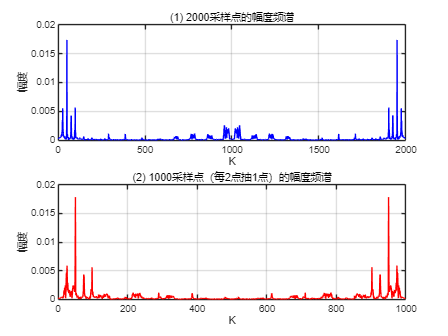

clc; clear; close all;
%% 1. 读取与截取数据
filename = 'motherland.wav';
if isfile(filename)
    [x, fs] = audioread(filename);
else
    % 如果没有文件，生成演示信号
    fs = 8000; 
    t = (0:2999)/fs;
    % 注意：为了模拟真实语音的小幅度，这里不要给太大
    x = sin(2*pi*500*t') + 0.5*sin(2*pi*3000*t'); 
end
% 截取第 1000 至 2999 点 (共 2000 点)
x_segment = x(1000:2999); 
%% 2. 分析原始 2000 采样点的幅度频谱 (上图)
N1 = length(x_segment);     % N1 = 2000
X_k = fft(x_segment);       
% --- 关键修改：除以 N1 进行归一化 ---
mag_X = abs(X_k) / N1;           
k_axis1 = 0 : N1-1;
figure('Name', '语音信号抽取前后的离散幅度频谱');
% 绘制第 1 幅图
subplot(2,1,1);
plot(k_axis1, mag_X, 'b'); % 蓝色
title('(1) 2000采样点的幅度频谱');
xlabel('K');
ylabel('幅度');
grid on;
xlim([0, 2000]); % 全频谱范围
%% 3. 抽取处理 (每 2 点抽 1 点)
y_decimated = x_segment(1:2:end); 
%% 4. 分析抽取后 1000 采样点的幅度频谱 (下图)
N2 = length(y_decimated);   % N2 = 1000
Y_k = fft(y_decimated);     
% --- 关键修改：除以 N2 进行归一化 ---
mag_Y = abs(Y_k) / N2;           
k_axis2 = 0 : N2-1;
% 绘制第 2 幅图
subplot(2,1,2);
plot(k_axis2, mag_Y, 'r'); % 红色
title('(2) 1000采样点（每2点抽1点）的幅度频谱');
xlabel('K');
ylabel('幅度');
grid on;
xlim([0, 1000]); % 全频谱范围